## BHZ model

### Useful matrix

%% useful tool
s_0   = pauli_matric(0)  ;  s_x = pauli_matric(1);  s_y =  pauli_matric(2) ;  s_z = pauli_matric(3);
sigma_0 = pauli_matric(0);sigma_x =  pauli_matric(1);sigma_y =  pauli_matric(2);sigma_z = pauli_matric(3);
tau_0   = pauli_matric(0);  tau_x =  pauli_matric(1);  tau_y =  pauli_matric(2);  tau_z = pauli_matric(3);

### k·p model

syms C0 C1 C2 real;
syms M0 M1 M2 real;
syms A B real;
syms k_x k_y k_z real;
%
M       = M0-M2*(k_x^2+k_y^2)-M1*(k_z^2);
E0k     = C0+C2*(k_x^2+k_y^2)+C1*(k_z^2);
k_plus  = k_x + 1i* k_y;
k_minus = k_x - 1i* k_y;
%
BHZ = HK(4,3)

BHZ =   HK - 属性:

    Basis_num: 4
        Basis: []
         Rank: 3
        Kinds: 20
        HcoeL: [4×4×20 sym]
        HnumL: [4×4×20 double]
        HstrL: ["1"    "x*y"    "x*z"    "y*z"    "x*y*z"    "x"    "y"    "z"    "x*Y"    "X*y"    "x*Z"    "X*z"    "y*Z"    "Y*z"    "X"    "Y"    "Z"    "x^3"    "y^3"    "z^3"]
        HsymL: [1×20 sym]
         Hfun: []
      HsymL_k: [1×20 sym]
       Hk_sym: [4×4 sym]
       Hk_num: []
     Hk_latex: '\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)'
           Rm: [3×3 double]
           Gk: [3×3 double]

\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)

%
BHZ = BHZ ...
    +Term(A*k_x ,sigma_z*tau_x )...
    +Term(A*k_y ,sigma_0*tau_y )...
    +Term(E0k   ,sigma_0*tau_0 )...
    +Term(M     ,sigma_0*tau_z )...
    +Term(B*k_z*(k_x^2-k_y^2),sigma_x*tau_x )...
    +Term(2*k_z*B*(k_x*k_y),sigma_y*tau_x )...
    ;

setting 6th (x) Hk


setting 7th (y) Hk


setting 1th (1) Hk
setting 15th (x^2) Hk
setting 16th (y^2) Hk
setting 17th (z^2) Hk


setting 1th (1) Hk
setting 15th (x^2) Hk
setting 16th (y^2) Hk
setting 17th (z^2) Hk


setting 12th (x^2*z) Hk
setting 14th (y^2*z) Hk


setting 5th (x*y*z) Hk


%
BHZ_PT = HK(4,2)

BHZ_PT =   HK - 属性:

    Basis_num: 4
        Basis: []
         Rank: 2
        Kinds: 10
        HcoeL: [4×4×10 sym]
        HnumL: [4×4×10 double]
        HstrL: ["1"    "x"    "y"    "z"    "x*y"    "x*z"    "y*z"    "X"    "Y"    "Z"]
        HsymL: [1×10 sym]
         Hfun: []
      HsymL_k: [1×10 sym]
       Hk_sym: [4×4 sym]
       Hk_num: []
     Hk_latex: '\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)'
           Rm: [3×3 double]
           Gk: [3×3 double]

\left(\begin{array}{cccc} 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)

%
BHZ_PT = BHZ_PT ...
    +Term(A*k_x ,sigma_z*tau_x )...
    +Term(A*k_y ,sigma_0*tau_y )...
    +Term(E0k   ,sigma_0*tau_0 )...
    +Term(M     ,sigma_0*tau_z )...
    +Term(B*(k_x^2-k_y^2),sigma_x*tau_x )...
    +Term(2*B*(k_x*k_y),sigma_y*tau_x )...
    ;

setting 2th (x) Hk


setting 3th (y) Hk


setting 1th (1) Hk
setting 8th (x^2) Hk
setting 9th (y^2) Hk
setting 10th (z^2) Hk


setting 1th (1) Hk
setting 8th (x^2) Hk
setting 9th (y^2) Hk
setting 10th (z^2) Hk


setting 8th (x^2) Hk
setting 9th (y^2) Hk


setting 5th (x*y) Hk


### Oper

Cubic = Oper.cubic(false,false);
C4 = Cubic(17);
C4.U = expm(diag([1i*pi/4,1i*3*pi/4,-1i*pi/4,-1i*3*pi/4]));
I = Oper.inversion(3,diag([1,-1,1,-1]));

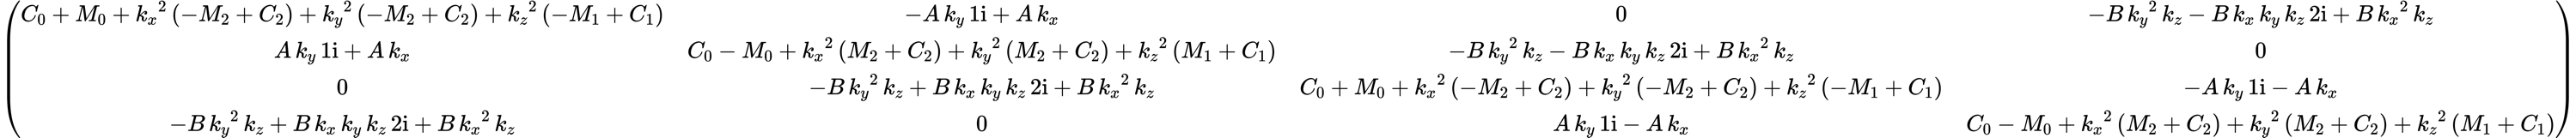

BHZ.applyOper(C4)

ans =   HK - 属性:

    Basis_num: 4
        Basis: []
         Rank: 3
        Kinds: 20
        HcoeL: [4×4×20 sym]
        HnumL: [4×4×20 double]
        HstrL: ["1"    "x*y"    "x*z"    "y*z"    "x*y*z"    "x"    "y"    "z"    "x*Y"    "X*y"    "x*Z"    "X*z"    "y*Z"    "Y*z"    "X"    "Y"    "Z"    "x^3"    "y^3"    "z^3"]
        HsymL: [1×20 sym]
         Hfun: []
      HsymL_k: [1×20 sym]
       Hk_sym: [4×4 sym]
       Hk_num: []
     Hk_latex: '\left(\begin{array}{cccc} C_{0}+M_{0}+{k_{x}}^2\,\left(-M_{2}+C_{2}\right)+{k_{y}}^2\,\left(-M_{2}+C_{2}\right)+{k_{z}}^2\,\left(-M_{1}+C_{1}\right) & -A\,k_{y}\,1{}\mathrm{i}+A\,k_{x} & 0 & -B\,{k_{y}}^2\,k_{z}-B\,k_{x}\,k_{y}\,k_{z}\,2{}\mathrm{i}+B\,{k_{x}}^2\,k_{z}\\ A\,k_{y}\,1{}\mathrm{i}+A\,k_{x} & C_{0}-M_{0}+{k_{x}}^2\,\left(M_{2}+C_{2}\right)+{k_{y}}^2\,\left(M_{2}+C_{2}\right)+{k_{z}}^2\,\left(M_{1}+C_{1}\right) & -B\,{k_{y}}^2\,k_{z}-B\,k_{x}\,k_{y}\,k_{z}\,2{}\mathr

BHZ.applyOper(I)

ans =   HK - 属性:

    Basis_num: 4
        Basis: []
         Rank: 3
        Kinds: 20
        HcoeL: [4×4×20 sym]
        HnumL: [4×4×20 double]
        HstrL: ["1"    "x*y"    "x*z"    "y*z"    "x*y*z"    "x"    "y"    "z"    "x*Y"    "X*y"    "x*Z"    "X*z"    "y*Z"    "Y*z"    "X"    "Y"    "Z"    "x^3"    "y^3"    "z^3"]
        HsymL: [1×20 sym]
         Hfun: []
      HsymL_k: [1×20 sym]
       Hk_sym: [4×4 sym]
       Hk_num: []
     Hk_latex: '\left(\begin{array}{cccc} C_{0}+M_{0}+{k_{x}}^2\,\left(-M_{2}+C_{2}\right)+{k_{y}}^2\,\left(-M_{2}+C_{2}\right)+{k_{z}}^2\,\left(-M_{1}+C_{1}\right) & -A\,k_{y}\,1{}\mathrm{i}+A\,k_{x} & 0 & -B\,{k_{y}}^2\,k_{z}-B\,k_{x}\,k_{y}\,k_{z}\,2{}\mathrm{i}+B\,{k_{x}}^2\,k_{z}\\ A\,k_{y}\,1{}\mathrm{i}+A\,k_{x} & C_{0}-M_{0}+{k_{x}}^2\,\left(M_{2}+C_{2}\right)+{k_{y}}^2\,\left(M_{2}+C_{2}\right)+{k_{z}}^2\,\left(M_{1}+C_{1}\right) & -B\,{k_{y}}^2\,k_{z}-B\,k_{x}\,k_{y}\,k_{z}\,2{}\mathr

BHZ_PT

BHZ_PT =   HK - 属性:

    Basis_num: 4
        Basis: []
         Rank: 2
        Kinds: 10
        HcoeL: [4×4×10 sym]
        HnumL: [4×4×10 double]
        HstrL: ["1"    "x"    "y"    "z"    "x*y"    "x*z"    "y*z"    "X"    "Y"    "Z"]
        HsymL: [1×10 sym]
         Hfun: []
      HsymL_k: [1×10 sym]
       Hk_sym: [4×4 sym]
       Hk_num: []
     Hk_latex: '\left(\begin{array}{cccc} C_{0}+M_{0}+{k_{x}}^2\,\left(-M_{2}+C_{2}\right)+{k_{y}}^2\,\left(-M_{2}+C_{2}\right)+{k_{z}}^2\,\left(-M_{1}+C_{1}\right) & -A\,k_{y}\,1{}\mathrm{i}+A\,k_{x} & 0 & -B\,{k_{y}}^2-B\,k_{x}\,k_{y}\,2{}\mathrm{i}+B\,{k_{x}}^2\\ A\,k_{y}\,1{}\mathrm{i}+A\,k_{x} & C_{0}-M_{0}+{k_{x}}^2\,\left(M_{2}+C_{2}\right)+{k_{y}}^2\,\left(M_{2}+C_{2}\right)+{k_{z}}^2\,\left(M_{1}+C_{1}\right) & -B\,{k_{y}}^2-B\,k_{x}\,k_{y}\,2{}\mathrm{i}+B\,{k_{x}}^2 & 0\\ 0 & -B\,{k_{y}}^2+B\,k_{x}\,k_{y}\,2{}\mathrm{i}+B\,{k_{x}}^2 & C_{0}+M_{0}+{k_{x}}^2\,\left(-M_{2}+

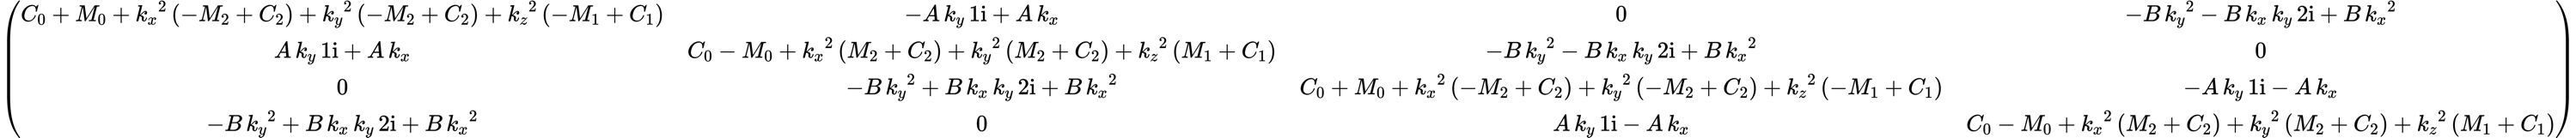

BHZ_PT.applyOper(I)

ans =   HK - 属性:

    Basis_num: 4
        Basis: []
         Rank: 2
        Kinds: 10
        HcoeL: [4×4×10 sym]
        HnumL: [4×4×10 double]
        HstrL: ["1"    "x"    "y"    "z"    "x*y"    "x*z"    "y*z"    "X"    "Y"    "Z"]
        HsymL: [1×10 sym]
         Hfun: []
      HsymL_k: [1×10 sym]
       Hk_sym: [4×4 sym]
       Hk_num: []
     Hk_latex: '\left(\begin{array}{cccc} C_{0}+M_{0}+{k_{x}}^2\,\left(-M_{2}+C_{2}\right)+{k_{y}}^2\,\left(-M_{2}+C_{2}\right)+{k_{z}}^2\,\left(-M_{1}+C_{1}\right) & -A\,k_{y}\,1{}\mathrm{i}+A\,k_{x} & 0 & 0\\ A\,k_{y}\,1{}\mathrm{i}+A\,k_{x} & C_{0}-M_{0}+{k_{x}}^2\,\left(M_{2}+C_{2}\right)+{k_{y}}^2\,\left(M_{2}+C_{2}\right)+{k_{z}}^2\,\left(M_{1}+C_{1}\right) & 0 & 0\\ 0 & 0 & C_{0}+M_{0}+{k_{x}}^2\,\left(-M_{2}+C_{2}\right)+{k_{y}}^2\,\left(-M_{2}+C_{2}\right)+{k_{z}}^2\,\left(-M_{1}+C_{1}\right) & -A\,k_{y}\,1{}\mathrm{i}-A\,k_{x}\\ 0 & 0 & A\,k_{y}\,1{}\mathrm{i}-A\,k_{x} & C_{

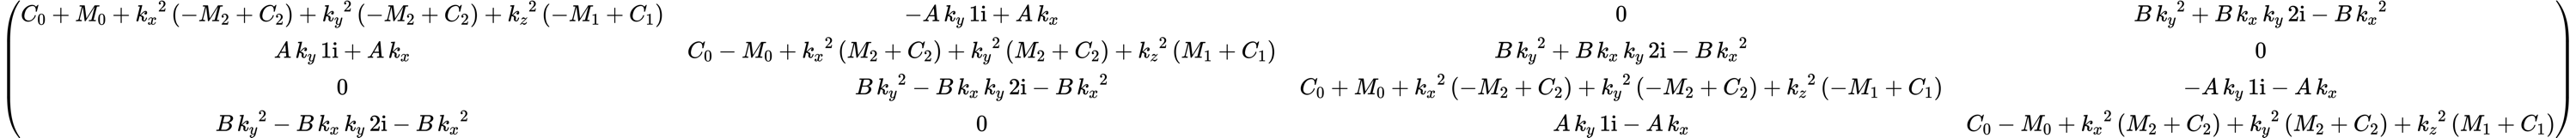

BHZ_PT.subsOper(I)

ans =   HK - 属性:

    Basis_num: 4
        Basis: []
         Rank: 2
        Kinds: 10
        HcoeL: [4×4×10 sym]
        HnumL: [4×4×10 double]
        HstrL: ["1"    "x"    "y"    "z"    "x*y"    "x*z"    "y*z"    "X"    "Y"    "Z"]
        HsymL: [1×10 sym]
         Hfun: []
      HsymL_k: [1×10 sym]
       Hk_sym: [4×4 sym]
       Hk_num: []
     Hk_latex: '\left(\begin{array}{cccc} C_{0}+M_{0}+{k_{x}}^2\,\left(-M_{2}+C_{2}\right)+{k_{y}}^2\,\left(-M_{2}+C_{2}\right)+{k_{z}}^2\,\left(-M_{1}+C_{1}\right) & -A\,k_{y}\,1{}\mathrm{i}+A\,k_{x} & 0 & 0\\ A\,k_{y}\,1{}\mathrm{i}+A\,k_{x} & C_{0}-M_{0}+{k_{x}}^2\,\left(M_{2}+C_{2}\right)+{k_{y}}^2\,\left(M_{2}+C_{2}\right)+{k_{z}}^2\,\left(M_{1}+C_{1}\right) & 0 & 0\\ 0 & 0 & C_{0}+M_{0}+{k_{x}}^2\,\left(-M_{2}+C_{2}\right)+{k_{y}}^2\,\left(-M_{2}+C_{2}\right)+{k_{z}}^2\,\left(-M_{1}+C_{1}\right) & -A\,k_{y}\,1{}\mathrm{i}-A\,k_{x}\\ 0 & 0 & A\,k_{y}\,1{}\mathrm{i}-A\,k_{x} & C_{

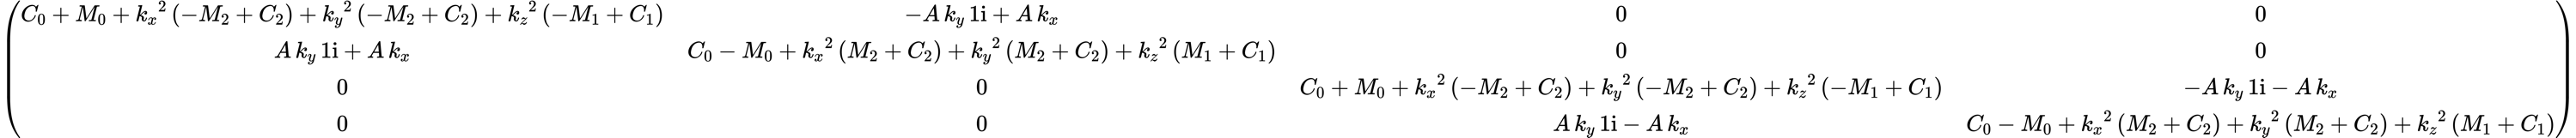

BHZ_building1 = HK(4,2);
BHZ_building1 = BHZ_building1 <= 'POSCAR';
J_mat = BHZ_building1.Jmat_gen();

Tr = Oper.time_reversal(3,double(-1i*sigma_y*tau_0),nan)

Tr =   Oper - 属性:

               R: [3×3 double]
               U: [4×4 double]
               t: [0 0 0]
       conjugate: 1
    antisymmetry: 0

U·H(k)*·U^-1 = H(-R·k)
R = 1
U = [0 0 -1 0;0 0 0 -1;1 0 0 0;0 1 0 0]

My = Oper.mirror([0,1,0],double(1i*sigma_y*tau_z),nan)

My =   Oper - 属性:

               R: [3×3 double]
               U: [4×4 double]
               t: [0 0 0]
       conjugate: 0
    antisymmetry: 0

U·H(k)·U^-1 = H(R·k)
R = M([0 1 0])
U = [0 0 1 0;0 0 0 -1;-1 0 0 0;0 1 0 0]

I = Oper.inversion(3,diag([1,-1,1,-1]))

I =   Oper - 属性:

               R: [3×3 double]
               U: [4×4 double]
               t: [0 0 0]
       conjugate: 0
    antisymmetry: 0

U·H(k)·U^-1 = H(R·k)
R = I
U = [1 0 0 0;0 -1 0 0;0 0 1 0;0 0 0 -1]


C4z = Oper.rotation(1/4,[0,0,1],false,sym(expm(1i*pi/4 *double(sigma_z*(tau_0-2*tau_z)))),nan,true);
C6z = Oper.rotation(1/6,[0,0,1],false,sym(expm(1i*pi/6 *double(sigma_z*(tau_0-2*tau_z)))),nan,true);
C3z = Oper.rotation(1/3,[0,0,1],false,sym(expm(1i*pi/3 *double(sigma_z*(tau_0-2*tau_z)))),nan,true);
groups = [Tr,My,I,C4z];
groups2 = [Tr,My,I,C6z];
groups3 = [Tr,My,I,C3z];
BHZ_building_C4 = BHZ_building1.applyOper(groups)

BHZ_building_C4 =   HK - 属性:

    Basis_num: 4
        Basis: []
         Rank: 2
        Kinds: 10
        HcoeL: [4×4×10 sym]
        HnumL: [4×4×10 double]
        HstrL: ["1"    "x"    "y"    "z"    "x*y"    "x*z"    "y*z"    "X"    "Y"    "Z"]
        HsymL: [1×10 sym]
         Hfun: []
      HsymL_k: [1×10 sym]
       Hk_sym: [4×4 sym]
       Hk_num: []
     Hk_latex: '\left(\begin{array}{cccc} A_{3,3,1}+A_{3,3,10}\,{k_{z}}^2+A_{3,3,9}\,{k_{y}}^2+A_{3,3,9}\,{k_{x}}^2 & 0 & 0 & B_{2,3,3}\,k_{y}\,1{}\mathrm{i}-B_{2,3,3}\,k_{x}\\ 0 & A_{4,4,1}+A_{4,4,10}\,{k_{z}}^2+A_{4,4,9}\,{k_{y}}^2+A_{4,4,9}\,{k_{x}}^2 & B_{2,3,3}\,k_{y}\,1{}\mathrm{i}-B_{2,3,3}\,k_{x} & 0\\ 0 & -B_{2,3,3}\,k_{y}\,1{}\mathrm{i}-B_{2,3,3}\,k_{x} & A_{3,3,1}+A_{3,3,10}\,{k_{z}}^2+A_{3,3,9}\,{k_{y}}^2+A_{3,3,9}\,{k_{x}}^2 & 0\\ -B_{2,3,3}\,k_{y}\,1{}\mathrm{i}-B_{2,3,3}\,k_{x} & 0 & 0 & A_{4,4,1}+A_{4,4,10}\,{k_{z}}^2+A_{4,4,9}\,{k_{y}}^2+A_{4,4,9}\,{k_{x}}

BHZ_building_C6 = BHZ_building1.applyOper(groups2)

BHZ_building_C6 =   HK - 属性:

    Basis_num: 4
        Basis: []
         Rank: 2
        Kinds: 10
        HcoeL: [4×4×10 sym]
        HnumL: [4×4×10 double]
        HstrL: ["1"    "x"    "y"    "z"    "x*y"    "x*z"    "y*z"    "X"    "Y"    "Z"]
        HsymL: [1×10 sym]
         Hfun: []
      HsymL_k: [1×10 sym]
       Hk_sym: [4×4 sym]
       Hk_num: []
     Hk_latex: '\left(\begin{array}{cccc} A_{3,3,1}+A_{3,3,10}\,{k_{z}}^2+A_{3,3,9}\,{k_{y}}^2+A_{3,3,9}\,{k_{x}}^2 & -\frac{k_{x}\,\left(4967757600021511\,B_{3,4,3}+81129638414606681695789005144064\,\sqrt{3}\,B_{3,4,3}\right)}{81129638414606681695789005144064\,\sqrt{3}-14903272800064533}+B_{3,4,3}\,k_{y}\,1{}\mathrm{i} & 0 & \frac{k_{x}\,\left(4967757600021511\,B_{2,3,3}-81129638414606681695789005144064\,\sqrt{3}\,B_{2,3,3}\right)}{81129638414606681695789005144064\,\sqrt{3}+14903272800064533}+B_{2,3,3}\,k_{y}\,1{}\mathrm{i}\\ -\frac{k_{x}\,\left(4967757600021511\,B_{3,4,3

BHZ_building_C6 = BHZ_building1.applyOper(groups2)
BHZ_building_C6 = BHZ_building1.applyOper(groups2)
BHZ_building_C3 = BHZ_building1.applyOper(groups3)

BHZ_building_C3 =   HK - 属性:

    Basis_num: 4
        Basis: []
         Rank: 2
        Kinds: 10
        HcoeL: [4×4×10 sym]
        HnumL: [4×4×10 double]
        HstrL: ["1"    "x"    "y"    "z"    "x*y"    "x*z"    "y*z"    "X"    "Y"    "Z"]
        HsymL: [1×10 sym]
         Hfun: []
      HsymL_k: [1×10 sym]
       Hk_sym: [4×4 sym]
       Hk_num: []
     Hk_latex: '\left(\begin{array}{cccc} A_{3,3,1}+A_{3,3,10}\,{k_{z}}^2+A_{3,3,9}\,{k_{y}}^2+A_{3,3,9}\,{k_{x}}^2 & \frac{k_{x}\,\left(4967757600021511\,B_{3,4,3}-40564819207303340847894502572032\,\sqrt{3}\,B_{3,4,3}\right)}{40564819207303340847894502572032\,\sqrt{3}+14903272800064533}+B_{3,4,3}\,k_{y}\,1{}\mathrm{i} & 0 & -\frac{k_{x}\,\left(4967757600021511\,B_{2,3,3}+40564819207303340847894502572032\,\sqrt{3}\,B_{2,3,3}\right)}{40564819207303340847894502572032\,\sqrt{3}-14903272800064533}+B_{2,3,3}\,k_{y}\,1{}\mathrm{i}\\ \frac{k_{x}\,\left(4967757600021511\,B_{3,4,3}


syms k_x k_y k_z k_plus k_minus real;